# Ordenamiento

Es el proceso de poner una lista en orden ya sea de forma descendente o ascendente 

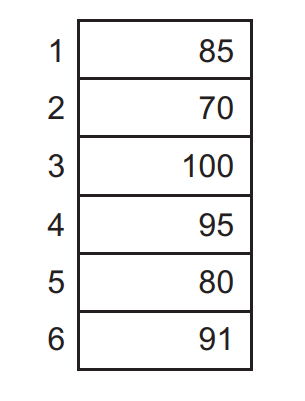

Suponemos que queremos ordenar la lista en forma ascendente

Se tiene un algoritmo basico:

- Observar el vector e identificar el numero mas pequenio y colocarlo en el primer elemento del vector. (Intercambiandolo con el numero del primer elemento actualmente).

- Luego, observar el resto del vector desde el segundo elemento para determinar el siguiente numero mas pequenio, cuando sea encontrado, colocalo en el primer elemento del resto del vector. (Intercambiandolo)

-  Continuar haciendo el proceso para el resto del vector. (El ultimo elemento se ubicara en la posicion correcta automaticamente)

## Representar el algoritmo en codigo

llamar la funcion

vector = [85,70,100,95,80,91]

vector =     85    70   100    95    80    91


vector = ordenarVector(vector)

vector =     70    80    85    91    95   100


## El metodo eficiente

Uso de la funcion sort()

Por defecto se ordena de manera ascendente

vector = sort(vector)

vector =     70    80    85    91    95   100


Crear la funcion

function vectorOrdenado = ordenarVector(vector)
    %Recorriendo los elementos del vector
    for i = 1:length(vector)-1 %Despues de cada iteracion del bucle exterior
                               %el elemento mas pequenio ya esta en la
                               %posicion correcta.
       idxMenor = i; %Almacenar el indice del numero mas pequenio
       %Determinar la posicion del numero mas peqenio
       for j = i+1:length(vector)
           if vector(j)<vector(idxMenor)
               idxMenor = j;
           end
       end

       %Intercambiar los elementos del vector
       vecT = vector(i);
       vector(i) = vector(idxMenor);
       vector(idxMenor) = vecT;
    end
    vectorOrdenado = vector;
end
    